theta_max = deg2rad(0.0002);
theta_dot_max = deg2rad(0.008);
phi_max = deg2rad(0.0003);
phi_dot_max = deg2rad(0.005);

Q = diag([(1/theta_max)^2 , (1/theta_dot_max)^2, (1/phi_max)^2, 1/phi_dot_max^2]);

u_max_az = 18;
u_max_el = 20;
R = diag([1/u_max_az^2, 1/u_max_el^2]);

process_noise_std = 1e-6;

I_theta = 0.75;
I_phi = 0.8;
damping = 0.15;

fps = 100000;
dt = 1/fps;
T_total = 15;
t = 1:dt:T_total;

A = [0 1 0 0;
     0 -damping/I_theta 0 0;
     0 0 0 1;
     0 0 0 -damping/I_phi];

B = [0 0;
     1/I_theta 0;
     0 0;
     0 1/I_phi];

[K,~,eigenvalues] = lqr(A, B, Q, R);
disp('Closed-loop eigenvalues:');

Closed-loop eigenvalues:


disp(eigenvalues);

   1.0e+05 *

   -0.0002
   -0.0004
   -1.7189
   -2.8648




az_deg = 100.0;
el_deg = -16.7;
target_theta = deg2rad(az_deg) * ones(size(t));
target_phi = deg2rad(el_deg) * ones(size(t));

y0 = [deg2rad(10); 0; deg2rad(5); 0];

telescope_dynamics = @(t, y, u) [
    y(2);
    (u(1) - damping * y(2)) / I_theta;
    y(4);
    (u(2) - damping * y(4)) / I_phi
];

y = zeros(4, length(t));
y(:,1) = y0;
u_history = zeros(2, length(t) - 1);

for i = 1:length(t) - 1
    theta_error = wrapToPi(y(1,i) - target_theta(i));
    phi_error = wrapToPi(y(3,i) - target_phi(i));
    
    u = -K * [theta_error; y(2,i); phi_error; y(4,i)];
    u = max(min(u, [u_max_az; u_max_el]), -[u_max_az; u_max_el]);
    u_history(:,i) = u;
    
    noise = process_noise_std * randn(4,1);
    
    k1 = telescope_dynamics(t(i), y(:,i), u);
    k2 = telescope_dynamics(t(i) + dt/2, y(:,i) + dt*k1/2, u);
    k3 = telescope_dynamics(t(i) + dt/2, y(:,i) + dt*k2/2, u);
    k4 = telescope_dynamics(t(i) + dt, y(:,i) + dt*k3, u);
    
    y(:,i+1) = y(:,i) + (dt/6)*(k1 + 2*k2 + 2*k3 + k4) + noise * dt;
end

steady_state_idx = floor(length(t)*0.25):length(t);
theta_error_ss = wrapToPi(y(1,steady_state_idx) - target_theta(steady_state_idx));
phi_error_ss = wrapToPi(y(3,steady_state_idx) - target_phi(steady_state_idx));

theta_rmse_deg_ss = rad2deg(sqrt(mean(theta_error_ss.^2) + eps));
phi_rmse_deg_ss = rad2deg(sqrt(mean(phi_error_ss.^2) + eps));

fprintf('Steady-State Performance Metrics:\n');

Steady-State Performance Metrics:


fprintf('Theta RMSE: %.10f° (%.4f arcsec)\n', theta_rmse_deg_ss, theta_rmse_deg_ss * 3600);

Theta RMSE: 0.0000008540° (0.0031 arcsec)


fprintf('Phi   RMSE: %.10f° (%.4f arcsec)\n', phi_rmse_deg_ss, phi_rmse_deg_ss * 3600);

Phi   RMSE: 0.0001271714° (0.4578 arcsec)


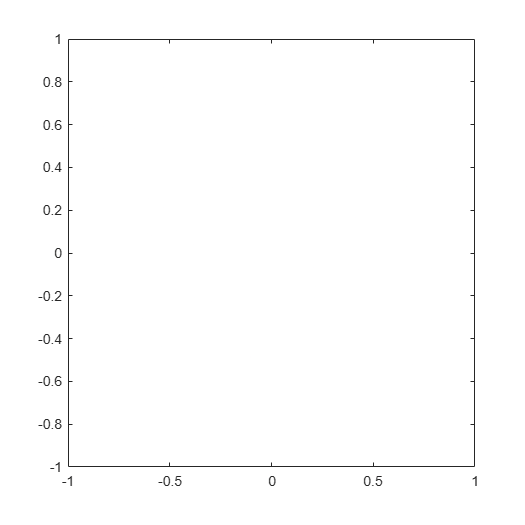


theta_error_full = wrapToPi(y(1,:) - target_theta);
phi_error_full = wrapToPi(y(3,:) - target_phi);

figure('Name','Telescope Control Performance','Position',[100 100 1200 800]);

subplot(2,2,1);
plot(t, rad2deg(y(1,:)), 'b-'); hold on;
plot(t, rad2deg(target_theta), 'r--'); hold off;
title('Azimuth Tracking');
legend('Actual', 'Target');
xlabel('Time (s)'); ylabel('Angle (°)');
grid on;

subplot(2,2,2);
plot(t, rad2deg(y(3,:)), 'b-'); hold on;
plot(t, rad2deg(target_phi), 'r--'); hold off;
title('Elevation Tracking');
legend('Actual', 'Target');
xlabel('Time (s)'); ylabel('Angle (°)');
grid on;

subplot(2,2,3);
plot(t(1:end-1), u_history(1,:), 'b-'); hold on;
plot(t(1:end-1), u_history(2,:), 'r-'); hold off;
title('Control Inputs');
legend('Azimuth Torque', 'Elevation Torque');
xlabel('Time (s)'); ylabel('Torque (N·m)');
grid on;

subplot(2,2,4);
plot(t, rad2deg(theta_error_full), 'b-'); hold on;
plot(t, rad2deg(phi_error_full), 'r-'); hold off;
title('Tracking Errors');
legend('Azimuth Error', 'Elevation Error');
xlabel('Time (s)'); ylabel('Error (°)');
grid on;

% 2D Tracking Animation with Angle Wrapping
arm_length = 1.0;
frame_step = round(fps/100);

fig = figure('Name','2D Telescope Tracking Animation (with Angle Wrapping)','Position',[200 200 600 600]);
ax = axes(fig);
set(ax, 'XLim', [-1.2 1.2] * arm_length, 'YLim', [-1.2 1.2] * arm_length);
axis(ax, 'equal');
grid(ax, 'on');
xlabel(ax, 'Azimuth Projection (x)');
ylabel(ax, 'Elevation Projection (y)');
title(ax, 'Telescope 2D Tracking with Angle Wrapping');

h_arm = plot(ax, [0,0], [0,0], 'b-', 'LineWidth', 3);

h_target = plot(ax, 0, 0, 'ro', 'MarkerSize', 10, 'LineWidth', 2);
h_text = text(ax, -1.1*arm_length, 1.1*arm_length, '', 'FontSize', 10, 'FontWeight', 'bold');

target_theta_wrapped = wrapToPi(target_theta(1));
target_phi_wrapped = wrapToPi(target_phi(1));
target_x = arm_length * cos(target_phi_wrapped) * cos(target_theta_wrapped);
target_y = arm_length * sin(target_phi_wrapped);
set(h_target, 'XData', target_x, 'YData', target_y);

for i = 1:frame_step:length(t)
    if ~isvalid(h_arm) || ~isvalid(fig)
        break;
    end
    try
        % Wrap angles before using them
        theta_wrapped = wrapToPi(y(1,i));
        phi_wrapped = wrapToPi(y(3,i));

        % Compute end-effector position based on wrapped angles
        x_pos = arm_length * cos(phi_wrapped) * cos(theta_wrapped);
        y_pos = arm_length * sin(phi_wrapped);

        % Update arm position
        set(h_arm, 'XData', [0, x_pos], 'YData', [0, y_pos]);

        % Update info text
        info_str = sprintf('Time: %.2fs | θ: %.4f° | φ: %.4f°', ...
            t(i), rad2deg(theta_wrapped), rad2deg(phi_wrapped));
        set(h_text, 'String', info_str);

        drawnow limitrate;
    catch ME
        warning('Animation error: %s', ME.message);
        break;
    end
end
%% Add Angle Wrapping Animation (after 2D tracking animation)

fig_wrap = figure('Name','Angle Wrapping Animation','Position',[100 100 1200 500]);

% Calculate errors
theta_error_raw = y(1,:) - target_theta;
phi_error_raw   = y(3,:) - target_phi;

theta_error_wrapped = wrapToPi(theta_error_raw);
phi_error_wrapped   = wrapToPi(phi_error_raw);

% Setup subplot for Azimuth error
subplot(1,2,1);
h_raw_theta = plot(NaN, NaN, 'r--', 'LineWidth', 1.5, 'DisplayName','Raw Error'); hold on;
h_wrap_theta = plot(NaN, NaN, 'b-', 'LineWidth', 2, 'DisplayName','Wrapped Error');
xlabel('Time (s)'); ylabel('Azimuth Error (°)');
title('Azimuth Angle Error Wrapping');
legend(); grid on; ylim([-400 400]);

% Setup subplot for Elevation error
subplot(1,2,2);
h_raw_phi = plot(NaN, NaN, 'r--', 'LineWidth', 1.5, 'DisplayName','Raw Error'); hold on;
h_wrap_phi = plot(NaN, NaN, 'b-', 'LineWidth', 2, 'DisplayName','Wrapped Error');
xlabel('Time (s)'); ylabel('Elevation Error (°)');
title('Elevation Angle Error Wrapping');
legend(); grid on; ylim([-400 400]);

% Animate angle wrapping error
for i = 1:frame_step:length(t)
    if ~isvalid(fig_wrap)
        break;
    end

    % Update plots
    set(h_raw_theta, 'XData', t(1:i), 'YData', rad2deg(theta_error_raw(1:i)));
    set(h_wrap_theta, 'XData', t(1:i), 'YData', rad2deg(theta_error_wrapped(1:i)));

    set(h_raw_phi, 'XData', t(1:i), 'YData', rad2deg(phi_error_raw(1:i)));
    set(h_wrap_phi, 'XData', t(1:i), 'YData', rad2deg(phi_error_wrapped(1:i)));

    drawnow limitrate;
end

